# Assignment Lecture06 Exercise

### 윤지상_2019092115

#### Exercise_06_01

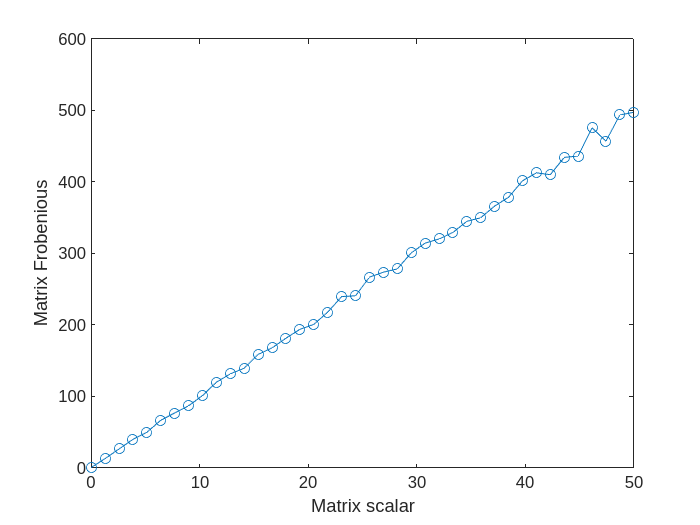

% The norm of a matrix is related to the scale of the numerical values in the matrix. In
% this exercise, you will create an experiment to demonstrate this. In each of 10
% experiment iterations, create a 𝟏𝟎 × 𝟏𝟎 random numbers matrix and compute its
% Frobenius norm. Then repeat this experiment 40 times, each time scalar multiplying
% the matrix by a different scalar that ranges between 0 and 50. The result of the
% experiment will be a 𝟒𝟎 × 𝟏𝟎 matrix of norms. Figure shows the resulting norms,
% averaged over the 10 experiment iterations. This experiment also illustrates two
% additional properties of matrix norms: they are strictly nonnegative and can equal 0
% only for the zeros matrix.

% Clear workspace, command window, and close all figures
clc; clear; close all;

%%%%%%%%%%%%%%%%% TODO %%%%%%%%%%%%%%%%%
% experiment simulations
% range of scaling parameters (0 to 50 in 40 steps)
%   hint: use linspace
scalingVals = linspace(0, 50, 40);

nExperiments = 10;

% initialize output
matrixNorms = zeros(length(scalingVals), nExperiments);

% run experiment
for si = 1:length(scalingVals)
  for expi = 1:nExperiments

    % generate a random scaled matrix
    m = scalingVals(si) * randn(10, 10);
    % store its norm Frobenius
    %frnorm = sqrt(trace(m'*m));
    frnorm = norm(m, 'fro');
    % matrixNorms
    matrixNorms(si, expi) = frnorm;
  end
end

% plot the results refer to figure of slide 100
mean_frnorm = mean(matrixNorms, 2);
plot(scalingVals, mean_frnorm, 'o-');
hold on;

xlabel('Matrix scalar');
ylabel('Matrix Frobenious');

xlim([0, 50]);
ylim([0, 600]);

#### Exercise_06_02

% I will now show you how to create random matrices with arbitrary rank (subject to
% the constraints about matrix sizes, etc.). To create an 𝑴 × 𝑵 matrix with rank r,
% multiply a random 𝑴 × 𝒓 matrix with an 𝒓 × 𝑵 matrix.
% Clear workspace, command window, and close all figures
clc; clear; close all;

%%%%%%%%%%%%%%%%% TODO %%%%%%%%%%%%%%%%%
% Make a matrix with specified size and rank
M = 10;
N = 7;
r = 6;

% consider A 
A = randn(M,r) * randn(r,N);

% calculate matrix A size and rank
size_m = size(A);
rank_m = rank(A);
% display size and rank
disp('Matrix A size:');

Matrix A size:


disp(size_m);

    10     7



disp('Rank A:');

Rank A:


disp(rank_m);

     6



#### Exercise_06_03

% Interestingly, the matrices 𝑨, 𝑨𝑻 , 𝑨𝑻 𝑨, and 𝑨𝑨𝑻 all have the same rank. Write code to
% demonstrate this, using random matrices of various sizes, shapes (square, tall, wide),
% and ranks.
% Clear workspace, command window, and close all figures
clc; clear; close all;

%%%%%%%%%%%%%%%%% TODO %%%%%%%%%%%%%%%%%
% matrix sizes and rank
M = 10;
N = 7;
r = 6;

% compute the four matrices
A = randn(M, r) * randn(r, N);
At = A'; % express A transpose using variable A
AtA = A' * A; % express A transpose using variable A
AAt = A * A'; % express A transpose using variable A

% calculate their ranks (A, At, AtA, AAt)
r_A = rank(A);
r_At = rank(At);
r_AtA = rank(AtA);
r_AAt = rank(AAt);

% print their ranks
% disp('ranks (A, At, AtA, AAt): ');
% disp([r_A r_At r_AtA r_AAt]);
fprintf('Rank of A: %d\n', r_A);

Rank of A: 6


fprintf('Rank of A transpose: %d\n', r_At);

Rank of A transpose: 6


fprintf('Rank of A transpose * A: %d\n', r_AtA);

Rank of A transpose * A: 6


fprintf('Rank of A * A transpose: %d\n', r_AAt);

Rank of A * A transpose: 6
